% sets font variables

set(0, 'defaultAxesFontSize', 12)

Makes Plot for Elongation Correlation Figure

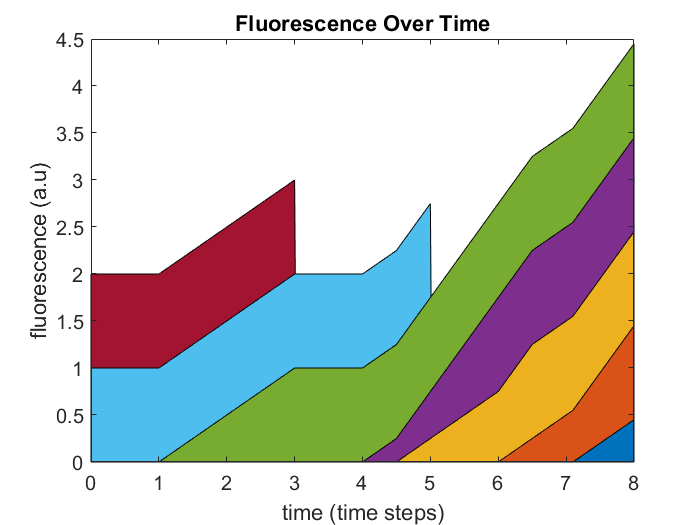

elong_time = 8;
rise_time = 2;
start_times = [-5, -3, 1,4,4.5,6,7.1];
colors = ['r', 'y', 'g', 'b', 'm', 'c', 'k'];

curves = [];
idx = 1;
for i = 0:0.01:8
    idx2 = 1;
    for time = flip(start_times)
        if time + elong_time >= i && time <= i
            val = min(1, (i - time) / rise_time);
        else
            val = 0;
        end
        curves(idx,idx2) = val;
        idx2 = idx2 + 1;
    end
    idx = idx + 1;
end

figure();
area(0:.01:8, curves);
xlabel('time (time steps)');
ylabel('fluorescence (a.u)');
title('Fluorescence Over Time');

Plots Autocorrelation for Shared Polymerases Alone

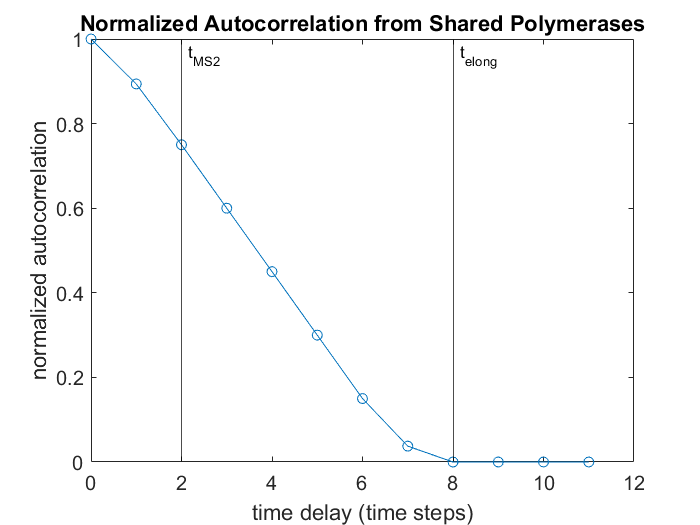

auto = zeros(1, 12);
auto0 = full_func_cor(8,2/8, 0, [], []);
for delay =  0:length(auto)-1
    [cor_tot, p_term, d_term] = full_func_cor(8,2/8,delay,1,1);
    auto(delay + 1) = p_term / auto0;
end
figure()
plot(0:11, auto, '-o')
xlabel('time delay (time steps)')
ylabel('normalized autocorrelation')
title('Normalized Autocorrelation from Shared Polymerases')
hold on
xline(2, 'Color', 'black', 'Label', 't_{MS2}', 'LabelOrientation', 'horizontal');
hold on
xline(8, 'Color', 'black', 'Label', 't_{elong}', 'LabelOrientation', 'horizontal');

Makes Plot for Dynamics Correlation Figure

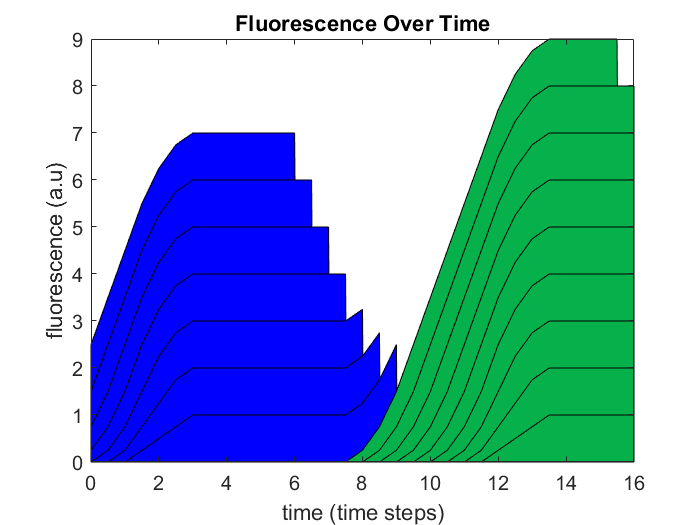

elong_time = 8;
rise_time = 2;
start_times = [-2,-1.5,-1,-0.5,0,0.5,1,...
    7.5,8,8.5,9,9.5,10,10.5,11,11.5];
colors = ['r', 'y', 'g', 'b', 'm', 'c', 'k'];

curves = [];
idx = 1;
for i = 0:0.01:16
    idx2 = 1;
    for time = flip(start_times)
        if time + elong_time >= i && time <= i
            val = min(1, (i - time) / rise_time);
        else
            val = 0;
        end
        curves(idx,idx2) = val;
        idx2 = idx2 + 1;
    end
    idx = idx + 1;
end

figure();
a = area(0:.01:16, curves, 'FaceColor', 'Blue');
for i = 1:9
    a(i).FaceColor = '#06B14C';
end
xlabel('time (time steps)');
ylabel('fluorescence (a.u)');
title('Fluorescence Over Time');

Plots Autocorrelation for Dynamics Correlation Alone

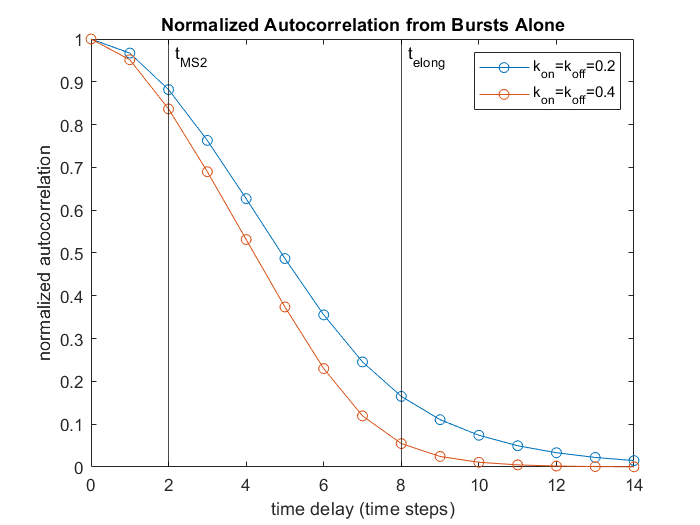

auto = zeros(1, 15);
auto_fast = zeros(1,15);
[cor_tot, p_term, d_term] = full_func_cor(8, 2/8, 0, 1, .4);
[~,~, auto0_fast] = full_func_cor(8,2/8,0,1,.8);
auto0 = d_term;
for delay =  0:length(auto)-1
    [cor_tot, p_term, d_term] = full_func_cor(8,2/8,delay,1,.4);
    auto(delay + 1) = d_term / auto0;
    [~,~,d_term_fast] = full_func_cor(8,2/8,delay,1,.8);
    auto_fast(delay + 1) = d_term_fast / auto0_fast;
end
figure()
plot(0:length(auto)-1, auto, '-o')
hold on
plot(0:length(auto)-1, auto_fast, '-o')
xlabel('time delay (time steps)')
ylabel('normalized autocorrelation')
title('Normalized Autocorrelation from Bursts Alone')

hold on
xline(2, 'Color', 'black', 'Label', 't_{MS2}', 'LabelOrientation', 'horizontal');
hold on
xline(8, 'Color', 'black', 'Label', 't_{elong}', 'LabelOrientation', 'horizontal');
legend('k_{on}=k_{off}=0.2', 'k_{on}=k_{off}=0.4')

Makes plot for second dynamics correlation example

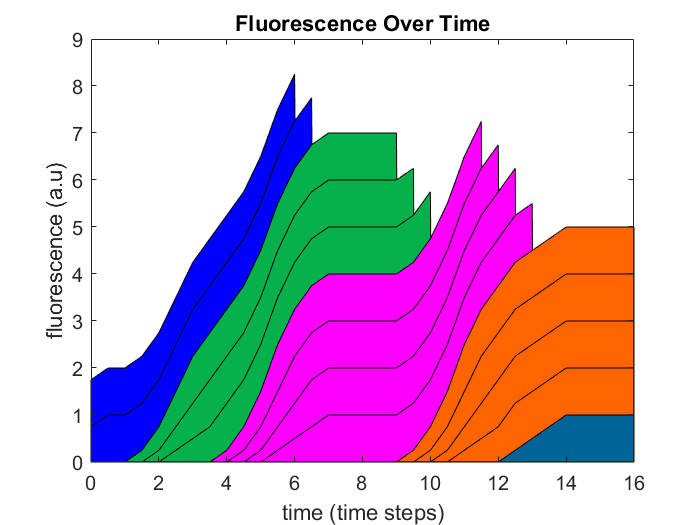

elong_time = 8;
rise_time = 2;
start_times = [-2,-1.5,1,1.5,2,3.5,4,4.5,5,9,9.5,10,10.5,12];
colors = ['r', 'y', 'g', 'b', 'm', 'c', 'k'];

curves = [];
idx = 1;
for i = 0:0.01:16
    idx2 = 1;
    for time = flip(start_times)
        if time + elong_time >= i && time <= i
            val = min(1, (i - time) / rise_time);
        else
            val = 0;
        end
        curves(idx,idx2) = val;
        idx2 = idx2 + 1;
    end
    idx = idx + 1;
end

figure();
a = area(0:.01:16, curves);
for i = 1:1
    a(i).FaceColor = '#006496';
end
for i = 2:5
    a(i).FaceColor = '#FF6400';
end
for i = 6:9
    a(i).FaceColor = '#FF00FF';
end
for i = 10:12
    a(i).FaceColor = '#06B14C';
end
for i = 13:14
    a(i).FaceColor = 'Blue';
end
xlabel('time (time steps)');
ylabel('fluorescence (a.u)');
title('Fluorescence Over Time');

Makes Plot of the Estimated Elongation Times

t_elongs = [72.7748, 94.7115, 126.282];
t_elong_sds = [10.4, 10.5, 10.5];
gene_lens = [1.9, 2.65, 3.4];

figure();
errorbar(gene_lens, t_elongs, t_elong_sds, 'o');
xlabel('gene length (kb)')
ylabel('elongation time (s)')

A = [1.9, 1; 2.65, 1; 3.4, 1];
cof = inv((A' * A)) * A';
x = cof * t_elongs';
m = x(1)

m = 35.6715

b = x(2)

b = 3.3934

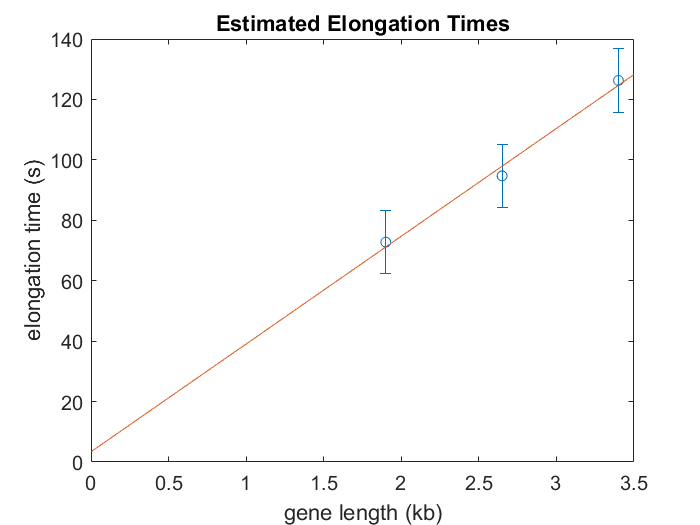


hold on
plot_range = 0:0.1:3.5;
plot(plot_range, m*plot_range + b);
title('Estimated Elongation Times')
xlim([0,3.5])


x_err = (cof.^2 * t_elong_sds'.^2).^0.5

x_err =     9.8525
   26.7533



yavg = mean(t_elongs);
R2 = 1 - sum((t_elongs - m*[1.9,2.65,3.4] + b).^2) ...
    / sum((t_elongs - yavg).^2)

R2 = 0.8938

Plots theoretical autocorrelation with shared polymerases and bursting terms

separated out

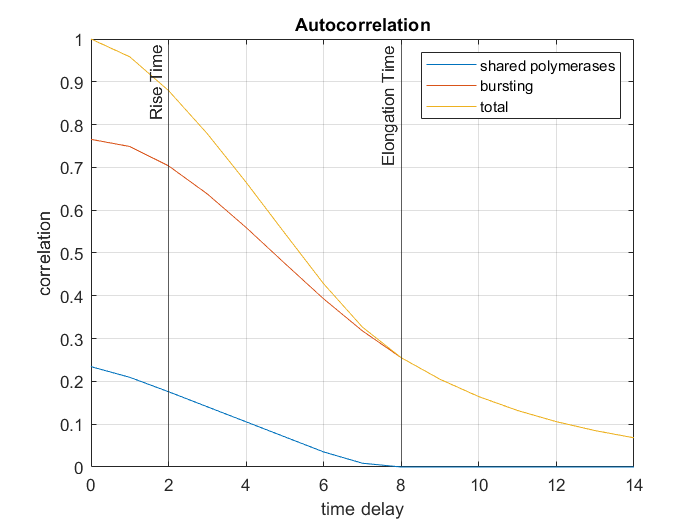

% plots elongation and dynamics contribution individually and together

kon = 0.02;
koff = 0.2;
b = kon + koff;
a = koff / sqrt(2 * (kon^2 + koff^2));
[cor_tot0, p_term0, d_term0] = full_func_cor(8, 2/8, 0, a, b);

cor_tots = zeros(1,15);
p_terms = zeros(1,15);
d_terms = zeros(1,15);

for delay =  0:length(cor_tots)-1
    [cor_tot, p_term, d_term] = full_func_cor(8,2/8,delay,a,b);
    cor_tots(delay+1) = cor_tot / cor_tot0;
    p_terms(delay+1) = p_term /cor_tot0;
    d_terms(delay+1) = d_term / cor_tot0;
end

figure();
plot(0:length(cor_tots)-1, p_terms);
hold on
plot(0:length(cor_tots)-1, d_terms);
hold on
plot(0:length(cor_tots)-1, cor_tots);
xline(2, '-', 'Rise Time', 'LabelHorizontalAlignment', 'left');
xline(8, '-', 'Elongation Time', 'LabelHorizontalAlignment', 'left');
legend({'shared polymerases', 'bursting', 'total'});
grid on
xlabel('time delay');
ylabel('correlation');
title('Autocorrelation')

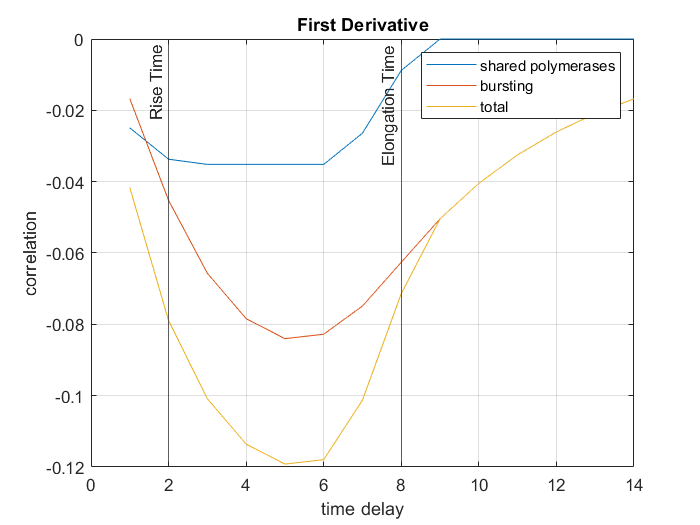


figure();

plot(1:length(cor_tots)-1, diff(p_terms));
hold on
plot(1:length(cor_tots)-1, diff(d_terms));
hold on
plot(1:length(cor_tots)-1, diff(cor_tots));
xline(2, '-', 'Rise Time', 'LabelHorizontalAlignment', 'left');
xline(8, '-', 'Elongation Time', 'LabelHorizontalAlignment', 'left');
legend({'shared polymerases', 'bursting', 'total'});
grid on
xlabel('time delay');
ylabel('correlation');
title('First Derivative')

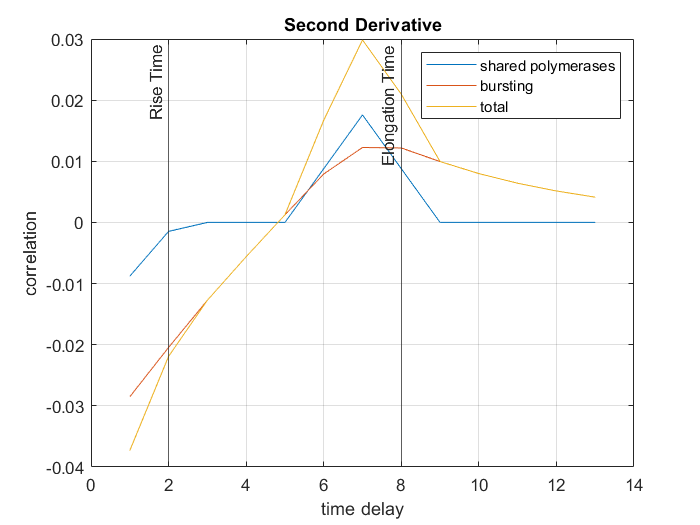


figure();

plot(1:length(cor_tots)-2, diff(diff(p_terms)));
hold on
plot(1:length(cor_tots)-2, diff(diff(d_terms)));
hold on
plot(1:length(cor_tots)-2, diff(diff(cor_tots)));
xline(2, '-', 'Rise Time', 'LabelHorizontalAlignment', 'left');
xline(8, '-', 'Elongation Time', 'LabelHorizontalAlignment', 'left');
legend({'shared polymerases', 'bursting', 'total'});
grid on
xlabel('time delay');
ylabel('correlation');
title('Second Derivative')

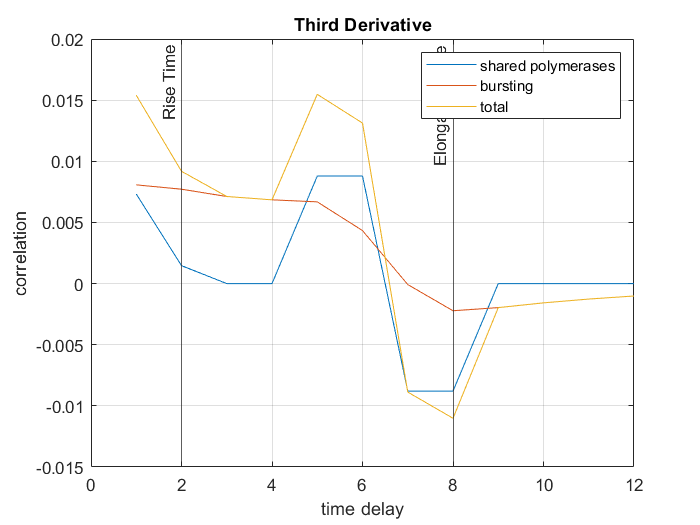


figure();

plot(1:length(cor_tots)-3, diff(diff(diff(p_terms))));
hold on
plot(1:length(cor_tots)-3, diff(diff(diff(d_terms))));
hold on
plot(1:length(cor_tots)-3, diff(diff(diff(cor_tots))));
xline(2, '-', 'Rise Time', 'LabelHorizontalAlignment', 'left');
xline(8, '-', 'Elongation Time', 'LabelHorizontalAlignment', 'left');
legend({'shared polymerases', 'bursting', 'total'});
grid on
xlabel('time delay');
ylabel('correlation');
title('Third Derivative')

Makes Plots Based On test_general_theroy.m results

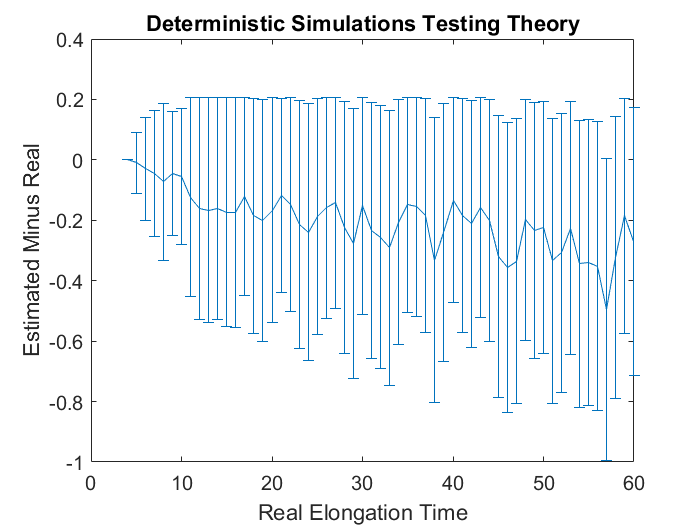

% preps variables
load('./../dat/comp_explore_res/comp_explorationg_07_10_21.mat');

possible_Ts = 4:100;
diff_means = zeros(1, length(possible_Ts));
diff_stds = zeros(1, length(possible_Ts));

for i = 1:length(possible_Ts)

    diff_means(i) = mean([dists([dists.T] == possible_Ts(i)).abs_min] - possible_Ts(i));
    diff_stds(i) = std([dists([dists.T] == possible_Ts(i)).abs_min] - possible_Ts(i));
end

figure()
errorbar(possible_Ts, diff_means, diff_stds);
xlabel('Real Elongation Time');
ylabel('Estimated Minus Real');
title('Deterministic Simulations Testing Theory');

Makes heatmap plot of errors from test_general_theory.m results

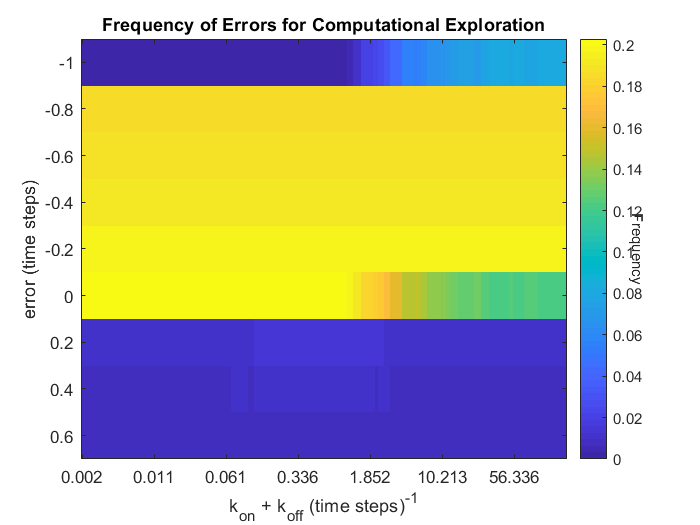

% preps variables
bs = zeros(1,length(dists));
Ts = zeros(1,length(dists));
errs = zeros(1,length(dists));
for i = 1:length(dists)
    bs(i) = dists(i).b;
    Ts(i) = dists(i).T;
    errs(i) = dists(i).abs_min - dists(i).T;
end

b_vals = sort(unique(round(bs,5)));
b_vals_norms = zeros(1, length(b_vals));
T_vals = sort(unique(floor(Ts)));
T_vals_norms = zeros(1, length(T_vals));
err_vals = sort(unique(round(errs, 2)));

b_matrix = zeros(length(b_vals), length(err_vals));
T_matrix = zeros(length(T_vals), length(err_vals));

for i = 1:length(bs)
    err_idx = find(err_vals == round(errs(i),2));
    b_idx = find(b_vals == round(bs(i),5));
    b_vals_norms(b_idx) = b_vals_norms(b_idx) + 1;
    T_idx = find(T_vals == floor(Ts(i)));
    T_vals_norms(T_idx) = T_vals_norms(T_idx) + 1;
    b_matrix(b_idx, err_idx) = b_matrix(b_idx, err_idx) + 1;
    T_matrix(T_idx, err_idx) = T_matrix(T_idx, err_idx) + 1;
end

rev_b_vals = log10(.002):log10(1.05):log10(200);
rev_b_vals_un = 10 .^ (rev_b_vals);
rev_b_matrix = zeros(length(rev_b_vals), length(err_vals));
rev_b_norms = zeros(1, length(rev_b_vals));

idxes = find(rev_b_vals_un <= b_vals(1));
rev_b_matrix(idxes,:) = repmat(b_matrix(1,:), length(idxes),1);
rev_b_norms(1, idxes) = repmat(b_vals_norms(1), 1,length(idxes));

for i = 2:length(b_vals)
    idxes = find(rev_b_vals_un <= b_vals(i) & rev_b_vals_un > b_vals(i-1));
    rev_b_matrix(idxes,:) = repmat(b_matrix(i,:), length(idxes),1);
    rev_b_norms(1,idxes) = repmat(b_vals_norms(i), 1,length(idxes));
end

% makes heat maps
figure();
imagesc(rev_b_vals, err_vals, rev_b_matrix' ./ rev_b_norms);
xticks(rev_b_vals(1:35:end));
xticklabels(round(rev_b_vals_un(1:35:end),3));
xlabel('k_{on} + k_{off} (time steps)^{-1}');
ylabel('error (time steps)');
title('Frequency of Errors for Computational Exploration')
h = colorbar;
ylabel(h, 'Frequency','Rotation',270.0)

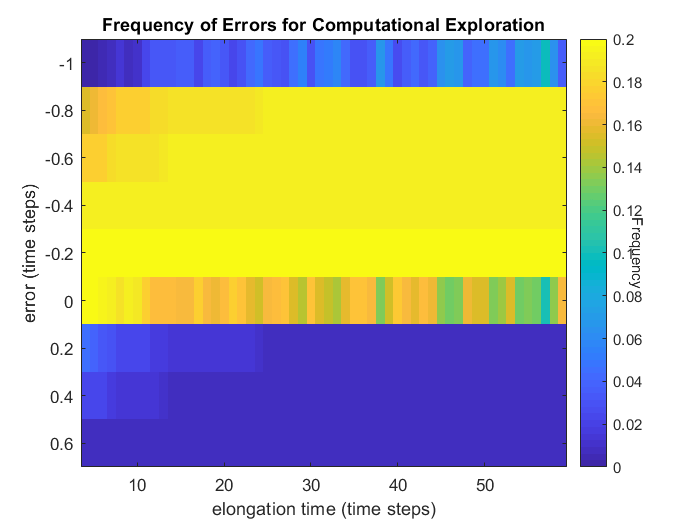



figure();
imagesc(T_vals(1:end-1), err_vals, T_matrix(1:end-1,1:end)' ./ T_vals_norms(1:end-1));
xlabel('elongation time (time steps)')
ylabel('error (time steps)');
title('Frequency of Errors for Computational Exploration')
h = colorbar;
ylabel(h, 'Frequency','Rotation',270.0)

Graphs the probability of remaining in the same state as a function of time

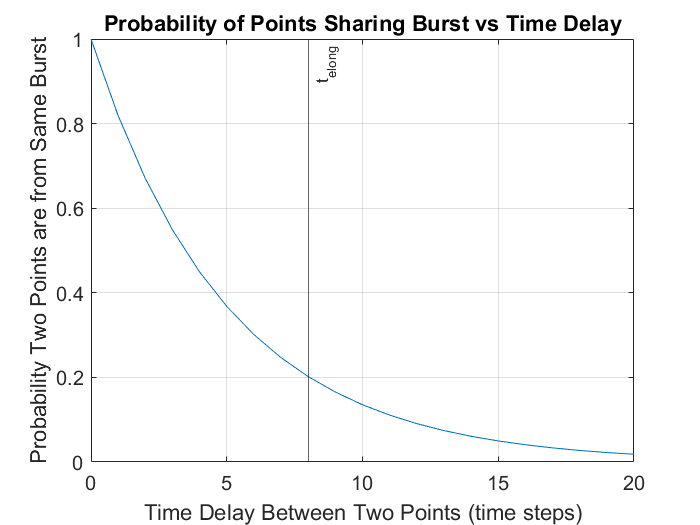

k = 0.2;
figure();
times = 0:20;
fun = @(t) exp(-t*k);
vals = fun(times);
plot(times, vals);
xline(8, 'Label', 't_{elong}');
xlabel('Time Delay Between Two Points (time steps)');
ylabel('Probability Two Points are from Same Burst');
title('Probability of Points Sharing Burst vs Time Delay');
grid on